# Hai Nguyen 16 April 2021

clear all; clc; close all;
rand('state',20);
randn('state',18);

## Initialize fake data

Mesh

n = 1000; sp = floor(n/10);
s = linspace(0,1,n+1)'; t = s;

% Discretize the deblurring kernel
beta = 0.05;
a = 1/sqrt(2*pi*beta^2)*exp(-0.5*(1/beta^2)*t.^2);
A = 1/n*toeplitz(a);

% Truth
xtrue = 10*(t-0.5).*exp(-0.5*1e2*(t-0.5).^2) -0.8 + 1.6*t;

% ------------additive noise-----------
noise = 5;       % Noise level in percentages of the max. of noiseless signal
y0 = A*xtrue;    % Noiseless signal
STD_noise = max(abs(y0))*noise/100;                % STD of the additive noise
y_obs = y0 + STD_noise*randn(n+1,1);

d = size(y_obs,1); p = size(xtrue,1);
% Data covariance
sigma_square = STD_noise^2;
SIGMA_SqR =  STD_noise * eye(d);
SIGMA_SqR_INV = 1/STD_noise * eye(d);

## Computations for different cases

alpha_square = [1e-4 0.0689261210434970 1e4];  % regularization parameters 
% alpha_square = [1e-4 0.0689261210434970 1e4];
R = [1 10];      % truncated value r
for i = 1:numel(alpha_square)
    for j = 1:numel(R)
        figure('Units','normalized','Position',[0 0 0.2 0.5]); hold on
        set(gca,'FontSize', 24, 'fontname', 'Times New Roman' )
        
        r = R(j);
        % x prior
        gamma = sqrt(sigma_square/alpha_square(i));
        GAMMA_SqR = gamma * eye(p);
        GAMMA_SqR_INV = 1/gamma * eye(p);
        
        % change of varibale ::: whitening x = \GAMMA_SqR * x_bar 
        A_bar = SIGMA_SqR_INV * A * GAMMA_SqR;
        y_obs_bar = SIGMA_SqR_INV * y_obs;

## Tikhonov solution

        K = A_bar; % for Tikhonov solution
        LHS = (K' * K + eye(p));
        RHS = K' * y_obs_bar;
        x_CM = GAMMA_SqR * (LHS \ RHS); % change back to x
        
        plot(s,xtrue,'k-','Linewidth',1.5,'DisplayName','Exact');
        plot(s,x_CM,'Color','k','Linestyle','-.','Marker','x','MarkerSize',12,'MarkerIndices',1:sp+4:length(x_CM),'Linewidth',1.5,'DisplayName','Tikhonov');

## Active subspace matrices

        C = A_bar' * (A_bar*A_bar' + y_obs_bar*y_obs_bar') * A_bar;
        [W,S_ddT,W] = svd(C);
        W1 = W(:,1:r);
        
        C_ACT_M = A_bar' * (A_bar * A_bar') * A_bar;
        [V,S_free,V] = svd(C_ACT_M);
        V1 = V(:,1:r);
        

## Active Subspace + approximated misfit!

        K = A_bar*W1*W1'; % for Tikhonov solution
        RHS = K' * y_obs_bar; % Construct right hand side
        LHS = K' * K + (eye(d) - W1 * W1');
        x_CM =  GAMMA_SqR * (LHS \ RHS);
        
        plot(s,x_CM,'Color','b','Linestyle','--','Marker','o','MarkerSize',12,'MarkerIndices',1:sp+2:length(x_CM),'Linewidth',1.5,'DisplayName','ACT');

## Active Subspace + approximated misfit + substracting gradient mean

        K = A_bar * V1 * V1'; % for Tikhonov solution
        RHS = K' * y_obs_bar; % Construct right hand side
        LHS = K' * K + (eye(d) - V1 * V1');
        x_CM =  GAMMA_SqR * (LHS \ RHS);
        
        plot(s,x_CM,'Color',[0.6350 0.0780 0.1840],'Linestyle','--','Marker','diamond','MarkerSize',12,'MarkerIndices',1:sp-2:length(x_CM),'Linewidth',1.5,'DisplayName','ACT-M');

## Active Subspace + full misfit

        K = A_bar; 
        RHS = K' * y_obs_bar;
        LHS = K' * K + (eye(d) - W1 * W1');
        x_CM =  GAMMA_SqR * (LHS \ RHS);
        
        plot(s,x_CM,'Color',[0.4660 0.6740 0.1880],'Linestyle','--','Marker','*','MarkerSize',12,'MarkerIndices',1:sp:length(x_CM),'Linewidth',1.5,'DisplayName','ACT-Full');

## Active Subspace + full misfit + substracting gradient mean

        K = A_bar; % for Tikhonov solution
        RHS = K' * y_obs_bar; % Construct right hand side
        LHS = (K' * K + (eye(p) - V1 * V1'));
        x_CM =  GAMMA_SqR * (LHS \ RHS);
        
        plot(s,x_CM,'Color','r','Linestyle','--','Marker','square','MarkerSize',12,'MarkerIndices',1:sp:length(x_CM),'Linewidth',1.5,'DisplayName','ACT-M-Full');
        

## Plot results

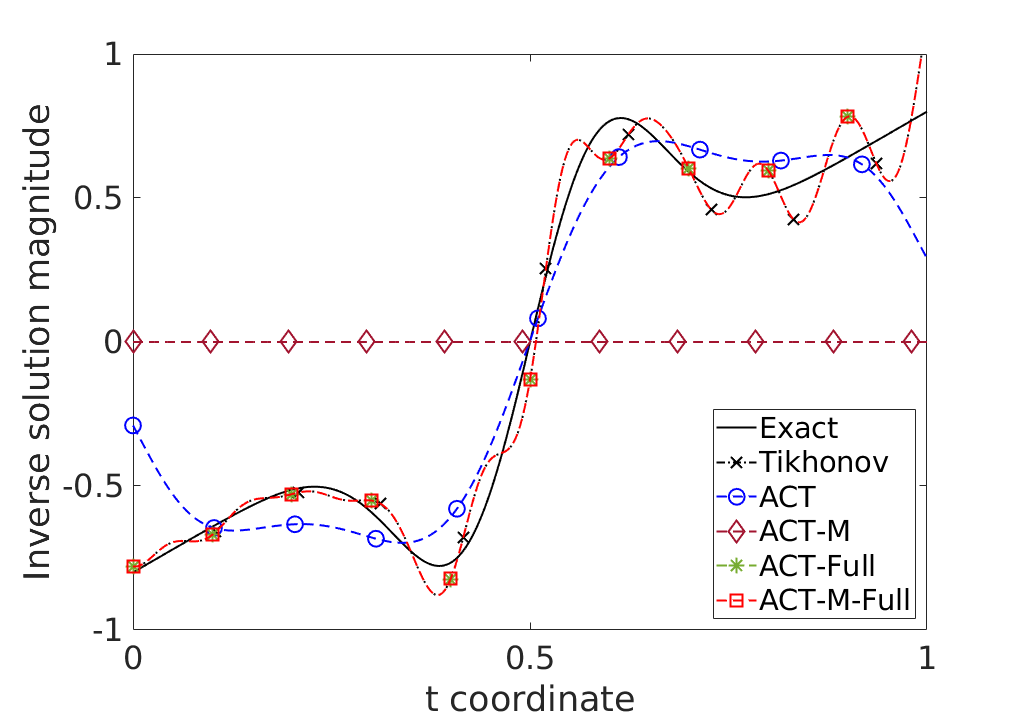

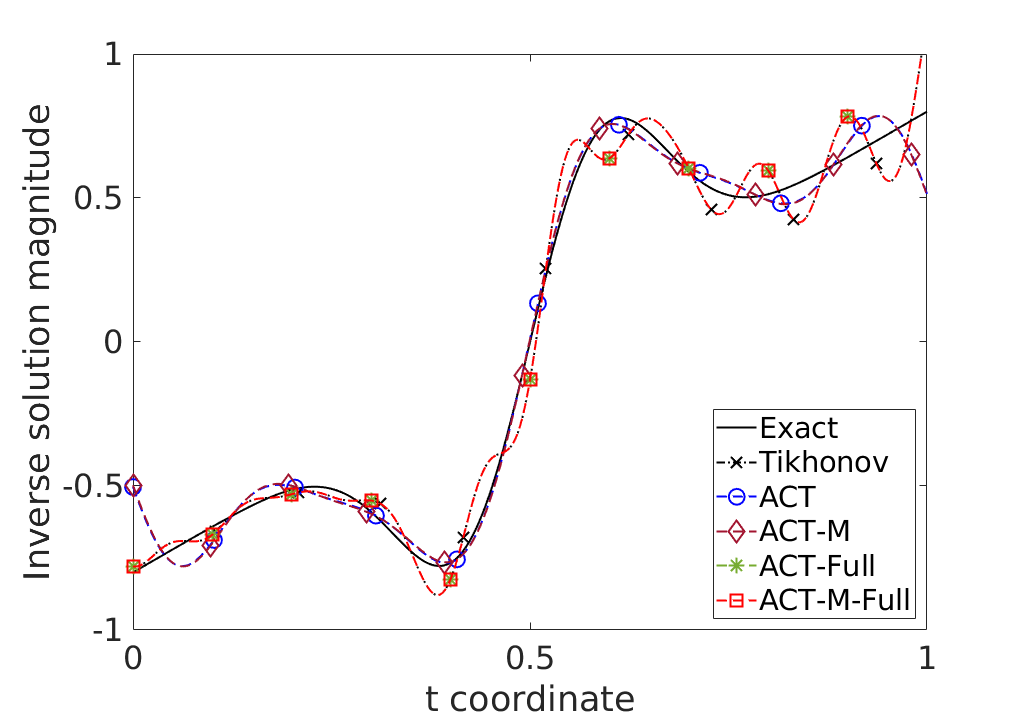

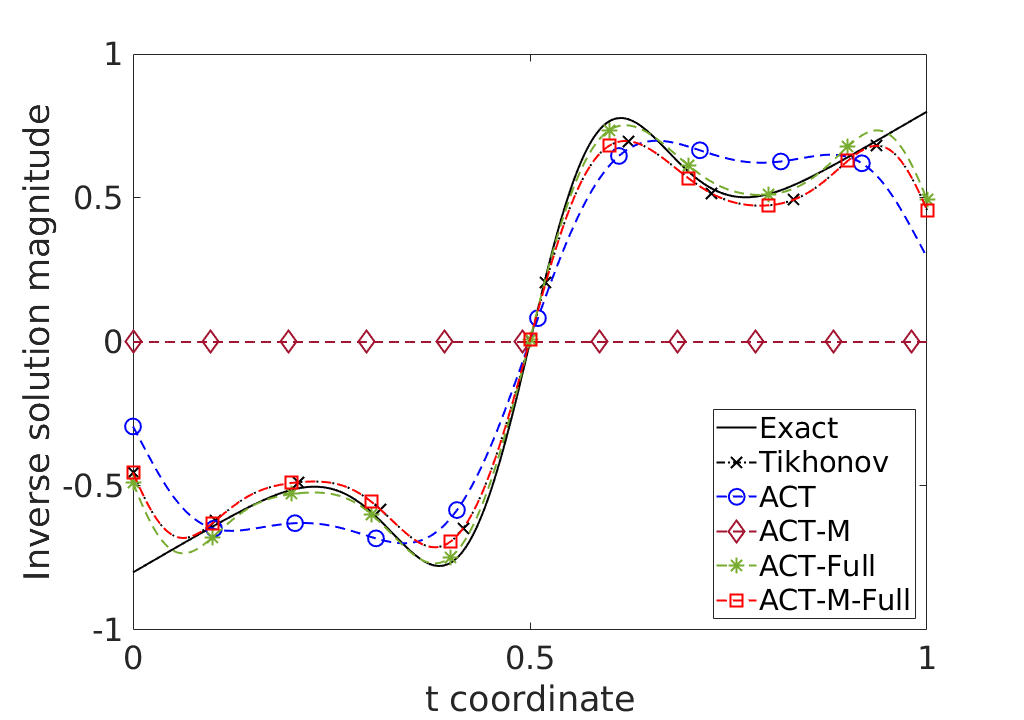

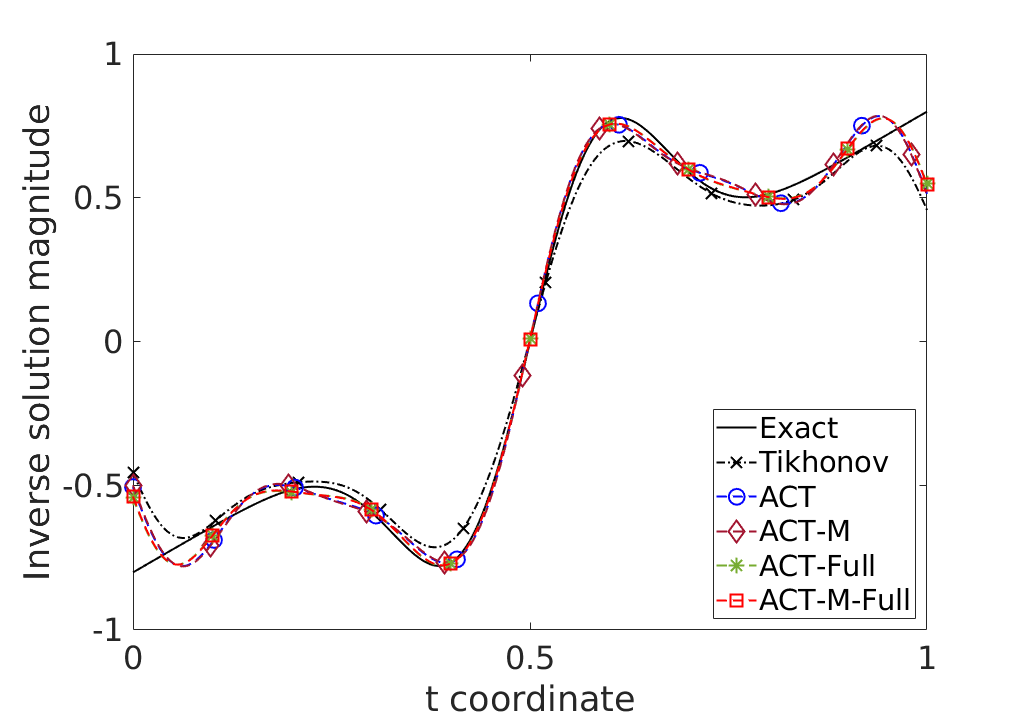

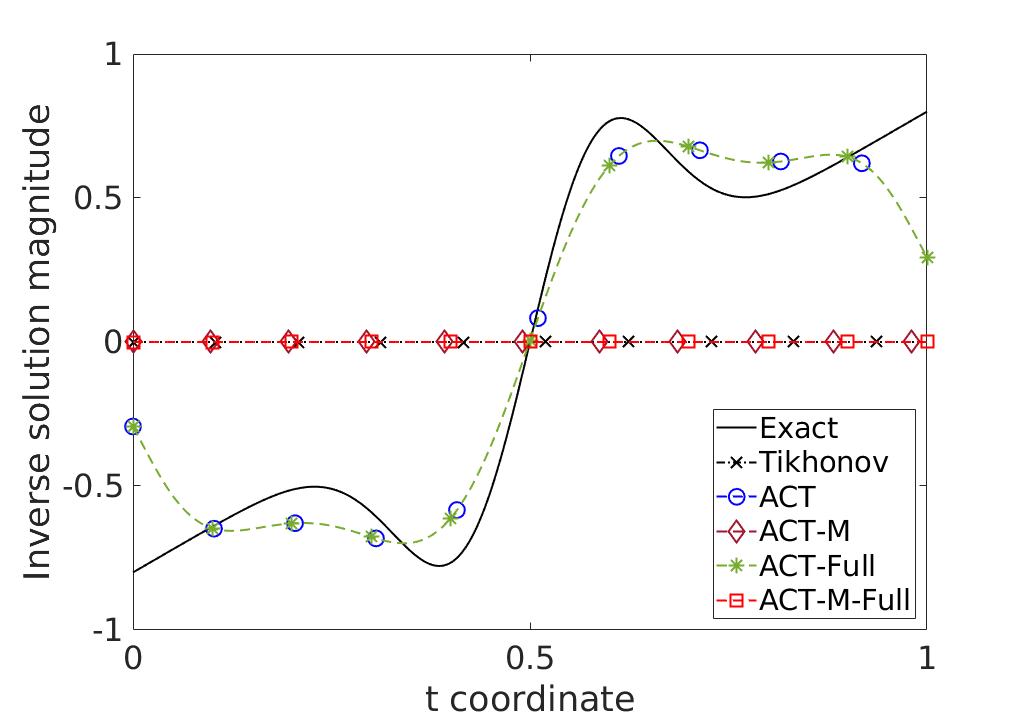

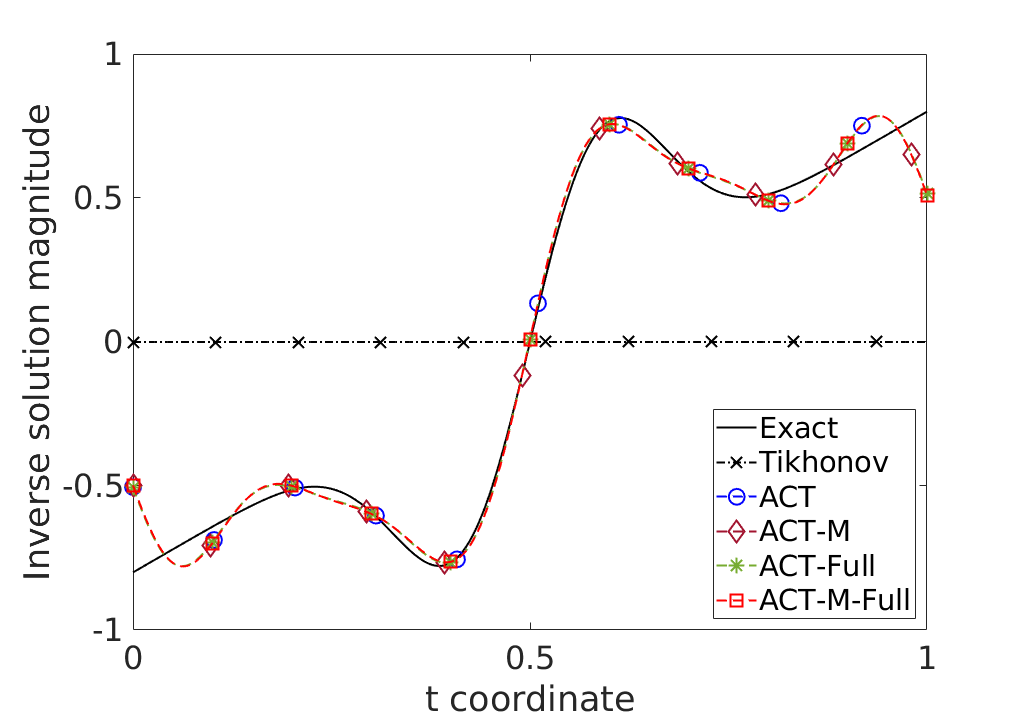

        xlabel('t coordinate')
        ylabel('Inverse solution magnitude')
        xticks([0 0.5 1])
        yticks([-1 -0.5  0 0.5 1])
        axis([0 1 -1 1]);
        
        legend('Location','southeast')
        box on
%         title(['r = ' num2str(r) ', \alpha = ' num2str(sigma_square/gamma^2)])
%         alpha_square(i)
%         
        if alpha_square(i) == 1e-4
            saveas(gcf,['1D_Decon_r_' num2str(r) '_alpha_0001'],'epsc')
        elseif  alpha_square(i) == 1e4
            saveas(gcf,['1D_Decon_r_' num2str(r) '_alpha_10000' ],'epsc')
        else
            saveas(gcf,['1D_Decon_r_' num2str(r) '_alpha_1' ],'epsc')
        end

        [i j]

ans =      1     1


ans =      1     2


ans =      2     1


ans =      2     2


ans =      3     1


ans =      3     2


    end
end